### `E7 - Introduction to Programming for Scientists and Engineers`

## `Discussion week 9`

# `Estimating the third bounce of a bouncing ball`

### Load the data

**Note:** `bouncing_ball.mat` contains a single 2D array called `position` whose first and second columns are respectively the `x` and `y` positions of the ball. 

clear
load('D:\Github\Berkeley\Engineering 7\Mar 20 Disc - WK9\bouncing_ball.mat')

px = position(:,1);
py = position(:,2);

### Plot the trajectory

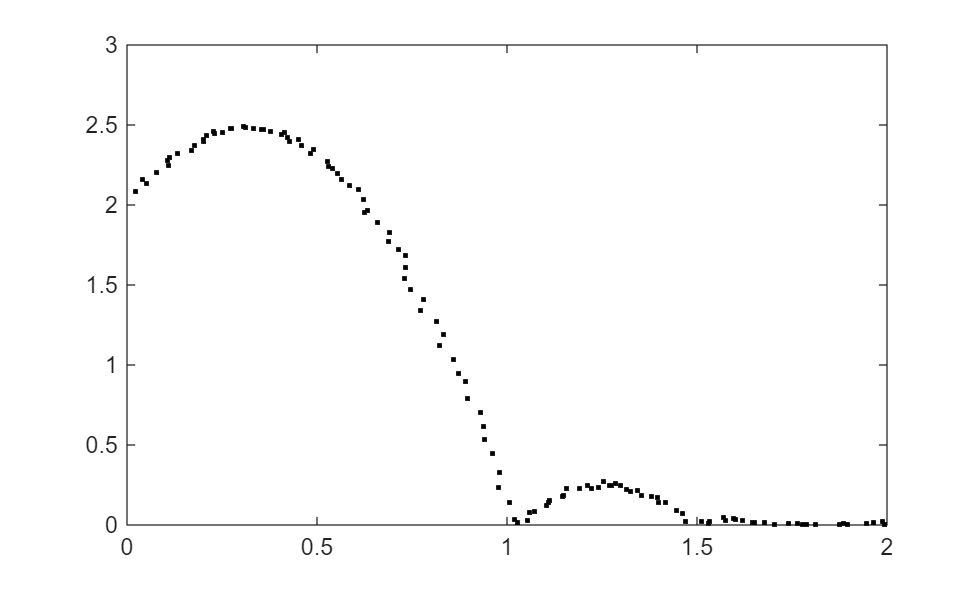

plot(px,py,'k.')
axis([0 2 0 3])

### 1) Estimate $x_{b1}$

mask_smallpy = py < 0.02 * max(py);
dn_mask = mask_smallpy(2:end) - mask_smallpy(1:end-1) > 0

dn_mask = 133×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


up_mask = mask_smallpy(2:end) - mask_smallpy(1:end-1) < 0

up_mask = 133×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


dn_mask = [false;dn_mask]

dn_mask = 134×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


up_mask = [false;up_mask]

up_mask = 134×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


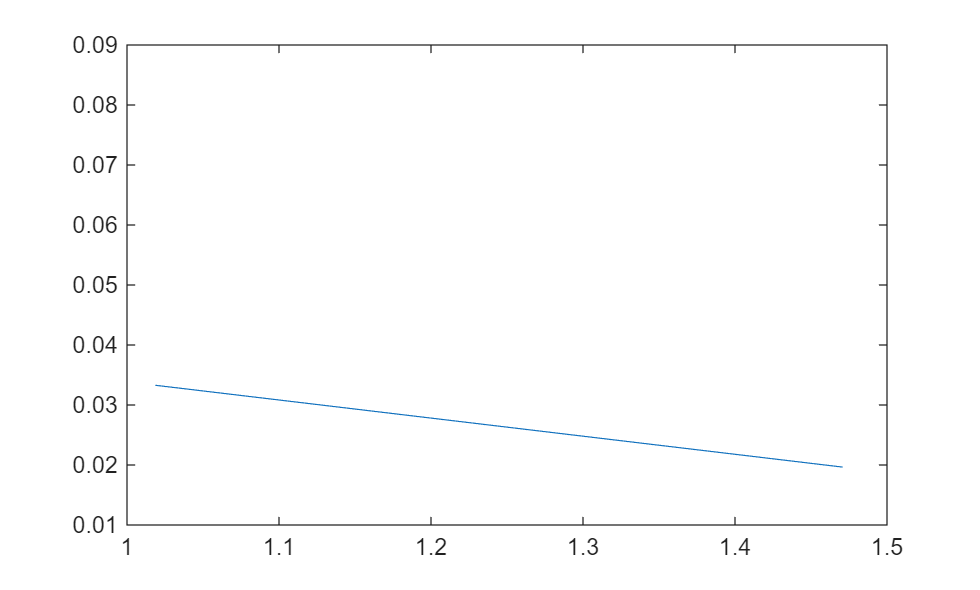


plot(px(dn_mask),py(dn_mask))
hold on
plot(px(dn_mask),py(up_mask))

### 2) Estimate $x_{p2}$

### 3) Estimate $x_{b2}$